% USE THE NORMAL MATLAB FILE
clear
clf; clc;
loadSim

Loading file: D05_08_h05_Ed_Asbc_R01
Loading file: D05_08_h05_Ef_Ab_03H01_R01
Loading file: D05_08_h05_Ef_Ab_05H01_R01
Loading file: D05_08_h05_Ef_Ab_05H05_R01
Loading file: D05_08_h05_Ef_Asbc_R01
Loading file: D05_13_h05_Ef_An_R01
Loading file: D05_13_h05_Ef_An_R02
Loading file: D05_13_h05_Ef_Asbc_R01
Loading file: D06_05_h05_Ea_An00H00_R01
Loading file: D06_05_h05_Eb_An00H00_R01
Loading file: D06_05_h05_Ed_As10H05_R01
Loading file: D06_05_h05_Ef_Ab05H02_R01
Loading file: D06_05_h05_Ef_Ab05H05_R01
Loading file: D06_05_h05_Ef_Ac05H0108_R01
Loading file: D06_05_h05_Ef_Ac08H0108_R01
Loading file: D06_05_h05_Ef_As03H02_R01
Loading file: D06_05_h05_Ef_As03H05_R01
Loading file: D06_05_h05_Ef_As03H10_R01
Loading file: D06_05_h05_Ef_As05H05_R01
Loading file: D06_05_h05_Ef_As07H02_R01
Loading file: D06_05_h05_Ef_As10H05_R01
Loading file: DC_bias
Elapsed time is 0.151694 seconds.
Data loaded


y_init = D05_08_h05_Ef_Asbc_R01.data(1,2);
y = D05_08_h05_Ef_Asbc_R01.data(2:end,2:3);
u = D05_08_h05_Ef_Asbc_R01.data(2:end,5);
z = iddata(y, u, 0.05, 'Name', 'Motor');
z.OutputName = {'Pendulum angle' 'Flywheel angular velocity'};
z.OutputUnit = {'rad' 'rad/s'};
z.InputName = {'Control Signal'};
z.Tstart = 0;
z.TimeUnit = 's';

FileName      = 'combined';        % File describing the model structure.
Order         = [2 1 3];             % Model orders [ny nu nx].

K1 = 10.8975;
K2 = 0.0393;
K3 = 0.1051;
K4 = 402;
K5 = 0.9403;
K6 = 1.7382;

K_tau = 0.01;
h = 0.05;

Parameters    = [K_tau];   % Initial parameters. %Jf,c_u,c_v
InitialStates = [y(1,1);(y(1,1)-y_init)/h;0]             % Initial initial states.

InitialStates =      0
     0
     0


Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Pendulum angle' 'Flywheel angular velocity'};
nlgr.OutputUnit = {'rad' 'rad/s'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Pendulum angle' 'Pendulum velocity' 'Flywheel velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad' 'rad/s' 'rad/s'});
nlgr = setpar(nlgr, 'Name', {'K_tau'});
nlgr = setpar(nlgr, 'Unit', {'-'});
nlgr = setpar(nlgr, 'Minimum', {eps(0)});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {inf});   % All parameters > 0.

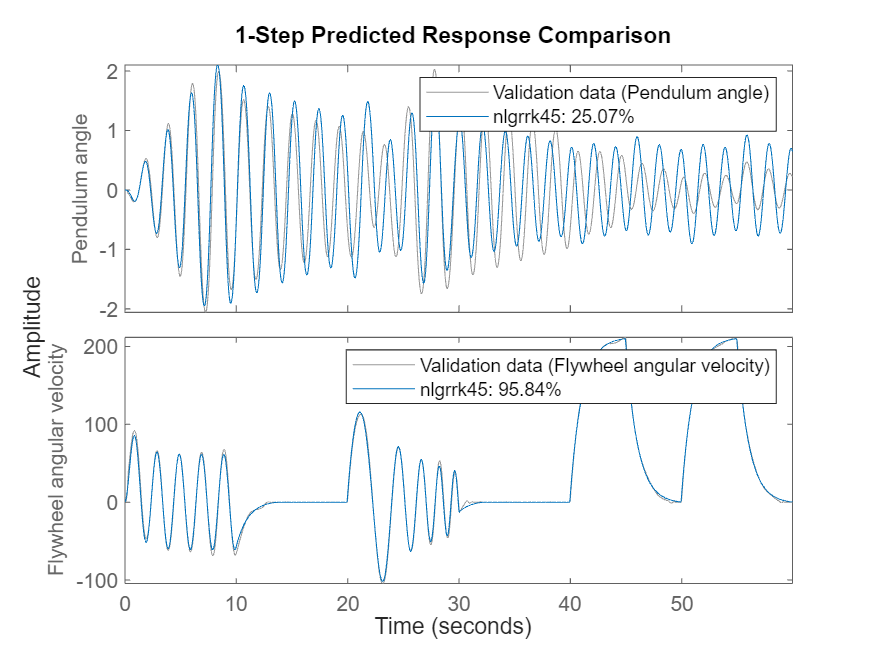


% C. Model computed with adaptive Runge-Kutta 45 ODE solver.
nlgrrk45 = nlgr;
nlgrrk45.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

figure(999);
compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45 = setpar(nlgrrk45, 'Fixed', {false});

opt = nlgreyestOptions('Display', 'on');
opt.SearchOptions.StepTolerance = 1e-3;
trk45 = clock;
nlgrrk45 = nlgreyest(z, nlgrrk45, opt);   % Perform parameter estimation.
trk45 = etime(clock, trk45);
figure(9999);

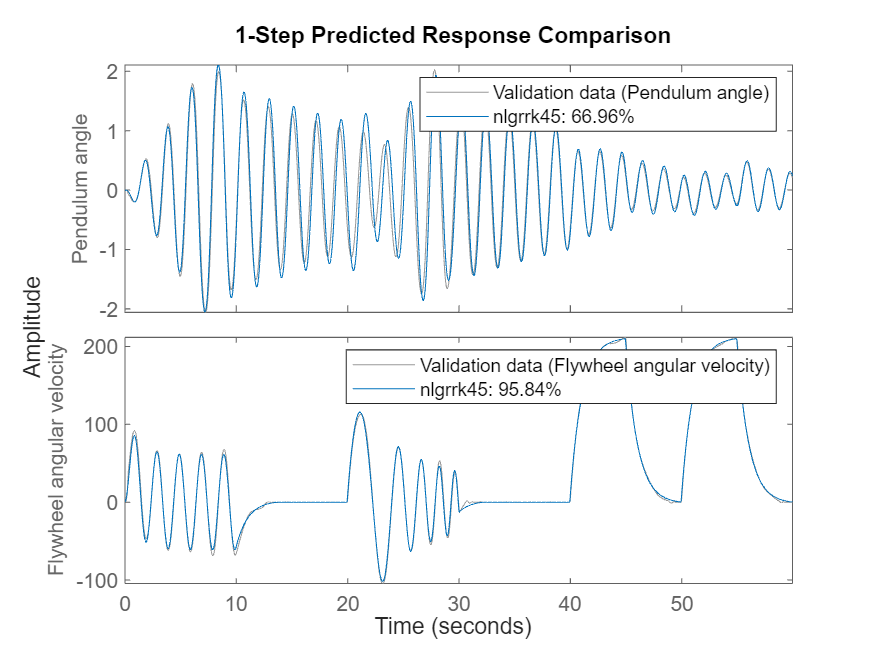

compare(z, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45.Parameters

ans = struct with fields:
       Name: 'K_tau'
       Unit: '-'
      Value: 0.0104
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 0


fpe(nlgrrk45);

    0.6678




nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'combined' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1)
    y(t) = H(t, u(t), x(t), p1) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 1 free parameter(s) (out of 1).

Status:                                                                      
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Motor".
Fit to estimation data: [67.1;95.84]%                                        
FPE: 0.6594, MSE: 9.671                                                      

Model Properties


ans = struct with fields:
       Name: 'K_tau'
       Unit: '-'
      Value: 0.0104
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 0



nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'combined' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1)
    y(t) = H(t, u(t), x(t), p1) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 1 free parameter(s) (out of 1).

Status:                                                                      
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Motor".
Fit to estimation data: [67.1;95.84]%                                        
FPE: 0.6594, MSE: 9.671                                                      

Model Properties


ans = struct with fields:
       Name: 'K_tau'
       Unit: '-'
      Value: 0.0104
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 0



nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'combined' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1)
    y(t) = H(t, u(t), x(t), p1) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 1 free parameter(s) (out of 1).

Status:                                                                      
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Motor".
Fit to estimation data: [67.1;95.84]%                                        
FPE: 0.6594, MSE: 9.671                                                      

Model Properties


ans = struct with fields:
       Name: 'K_tau'
       Unit: '-'
      Value: 0.0104
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 0



nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'combined' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1)
    y(t) = H(t, u(t), x(t), p1) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 1 free parameter(s) (out of 1).

Status:                                                                      
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Motor".
Fit to estimation data: [67.1;95.84]%                                        
FPE: 0.6594, MSE: 9.671                                                      

Model Properties


ans = struct with fields:
       Name: 'K_tau'
       Unit: '-'
      Value: 0.0104
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 0



nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'combined' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1)
    y(t) = H(t, u(t), x(t), p1) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 1 free parameter(s) (out of 1).

Status:                                                                      
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Motor".
Fit to estimation data: [67.1;95.84]%                                        
FPE: 0.6594, MSE: 9.671                                                      

Model Properties


ans = struct with fields:
       Name: 'K_tau'
       Unit: '-'
      Value: 0.0104
    Minimum: 4.9407e-324
    Maximum: Inf
      Fixed: 0


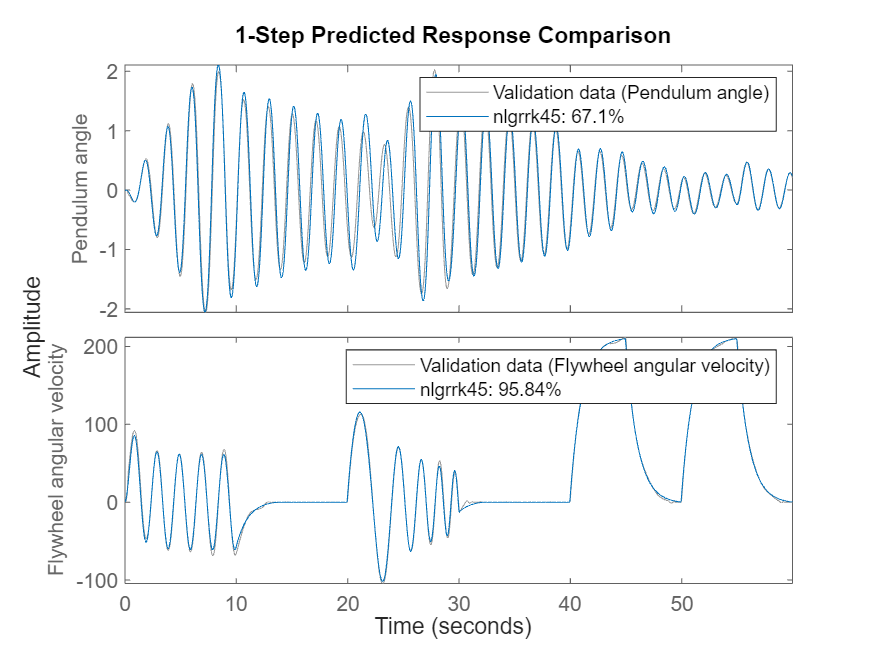


for i = 1:5
    nlgrrk45 = nlgreyest(z,nlgrrk45, opt)

    nlgrrk45.Parameters
    figure(i),clf;
        compare(z, nlgrrk45, 1, ...
        compareOptions('InitialCondition', 'model'));
end